theta = 0:1:179; % 投影角度

% 计算 Radon 变换（假设旋转中心和初始角度未知）
F2 = iradon(File2, theta, 'linear', 'Ram-Lak', 1, 512);
I = imresize(F2,0.5);
I1 = File1;
R = radon(I1);

% 定义目标函数，用于优化旋转中心和初始角度以及角度偏移
function error = objective_function(params, I, R)
    % 提取参数
    cx = params(1);
    cy = params(2);
    initial_angle = params(3);
    theta_offsets = params(4:end); % 180 个角度偏移
    
    % 平移图像，使得旋转中心与图像中心对齐
    translation = [cx, cy] - size(I) / 2;
    tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
    I_translated = imwarp(I, tform, 'OutputView', imref2d(size(I)));
    
    % 旋转图像，使得初始角度为 0
    I_rotated = imrotate(I_translated, -initial_angle, 'bilinear', 'crop');
    
    % 更新 theta
    theta = theta_offsets + theta_offsets;
    
    % 计算 Radon 变换
    R_estimated = radon(I_rotated, theta);
    
    % 计算误差
    error = norm(R - R_estimated, 'fro');
end

% 初始猜测参数 [cx, cy, initial_angle, theta_offsets]
initial_params = [size(I, 2) / 2, size(I, 1) / 2, 0, zeros(1, 180)];

% 优化参数使用遗传算法
options = optimoptions('ga', 'Display', 'iter', 'UseParallel', true);

% 设置参数的上下限
lb = [0, 0, -180, -10*ones(1, 180)]; % 下限
ub = [size(I, 2), size(I, 1), 180, 10*ones(1, 180)]; % 上限

% 使用遗传算法优化
optimized_params = ga(@(params) objective_function(params, I, R), 183, [], [], [], [], lb, ub, [], options);


Single objective optimization:
183 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400       1.135e+04       1.308e+04        0
    2              590       1.134e+04       1.261e+04        0
    3              780       1.133e+04       1.222e+04        0
    4              970       1.129e+04       1.192e+04        0
    5             1160       1.127e+04       1.172e+04        0
    6             1350       1.127e+04       1.156e+04        0
    7             1540       1.126e+04       1.148e+04        0
    8             1730       1.124e+04       1.141e+04        0
    9             1920       1.124e+04       1.134e+04        1
   10             2110       1.123e+04       1.131e+04        0
   11      


% 提取优化后的参数
estimated_center_x = optimized_params(1);
estimated_center_y = optimized_params(2);
estimated_initial_angle = optimized_params(3);
estimated_theta_offsets = optimized_params(4:end);

% 打印结果
fprintf('估计的旋转中心: (%.2f, %.2f)\n', estimated_center_x, estimated_center_y);

估计的旋转中心: (117.31, 117.01)


fprintf('估计的初始旋转角度: %.2f 度\n', estimated_initial_angle);

估计的初始旋转角度: -0.26 度


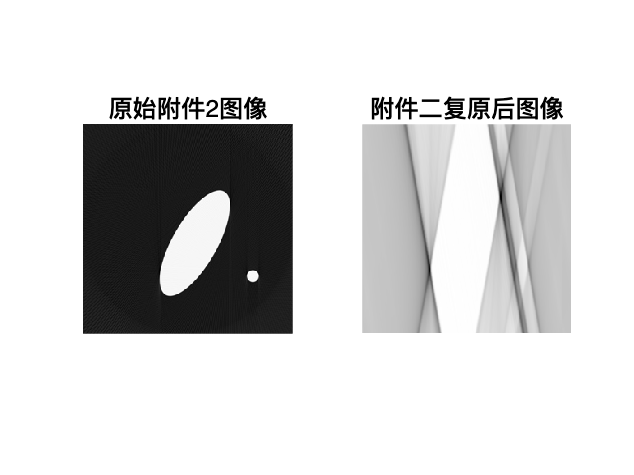


% 使用估计的旋转中心和初始角度进行逆 Radon 变换
% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I) / 2;
tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I_translated = imwarp(I, tform, 'OutputView', imref2d(size(I)));

% 旋转图像，使得初始角度为 0
I_rotated = imrotate(I_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 更新 theta
theta = estimated_initial_angle + estimated_theta_offsets;

% 计算 Radon 变换
R_estimated = radon(I_rotated, theta);

% 使用逆 Radon 变换复原图像
I_reconstructed = iradon(R_estimated, theta);

% 绘制原始图像和复原图像
figure;
subplot(1,2,1);
imshow(I, []);
title('原始附件2图像');

subplot(1,2,2);
imshow(I_reconstructed, []);
title('附件二复原后图像');